% 1. Ábra előkészítése
figure('Name', 'Path tervező', 'NumberTitle', 'off');
axis([0 100 0 100]); 
grid on; hold on;
xlabel('X koordináta [m]'); ylabel('Y koordináta [m]');
title('Kattints a kanyarok CSÚCSAINAK lerakásához! (Befejezés: ENTER)');

% Kezdeti üres vektorok
x_coords = [];
y_coords = [];

% "Élő" vonal: ez most a pálya "külső széle" lesz, amiben a sarkok vannak
h_raw_plot = plot(nan, nan, '--k', 'LineWidth', 1, 'Marker', 'o', 'MarkerFaceColor', 'y', 'DisplayName', 'Kattintott (Külső) Ív');

disp('Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.');

Kattints az út rajzolásához! Nyomj ENTER-t a záráshoz.



% 2. Interaktív kattintós ciklus
while true
    [x_new, y_new, ~] = ginput(1);
    if isempty(x_new), break; end

    x_coords = [x_coords; x_new];
    y_coords = [y_coords; y_new];

    set(h_raw_plot, 'XData', x_coords, 'YData', y_coords);
    drawnow;
end

% 3. Ideális ív (Racing Line) generálása
if numel(x_coords) >= 3
    disp('Számolás: Pálya generálás...');

    % Zárjuk be a vonalat
    x_coords = [x_coords; x_coords(1)];
    y_coords = [y_coords; y_coords(1)];

    % Fizikai távolságok kiszámítása
    distances = sqrt(diff(x_coords).^2 + diff(y_coords).^2);
    t = [0; cumsum(distances)]; 

    % 1. LÉPÉS: Nagyon sűrű "nyers" szögletes vonal (10 cm-es felbontás)
    t_finom = 0:0.1:t(end); 
    x_lin = interp1(t, x_coords, t_finom, 'linear');
    y_lin = interp1(t, y_coords, t_finom, 'linear');
end

Számolás: Pálya generálás...


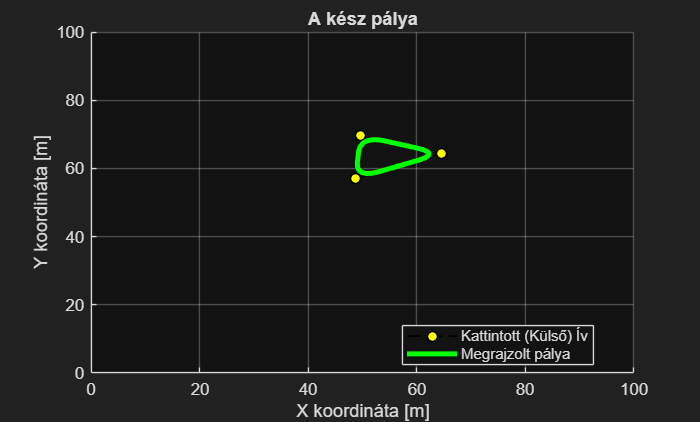

function [InitialObservation, LoggedSignals] = myResetFunction()
    % Itt állítod vissza a CasADi rendszert a startvonalra
    global x_real z_nom MPC_k
    
    % Kezdeti állapot (pl. [0;0;0;0])
    x_real = [0; 0; 0; 0];
    z_nom = [0; 0; 0; 0];
    MPC_k = 1; % Időlépés számláló
    
    % Kezdeti megfigyelés: [e_x, e_y, vx, vy, prev_err]
    InitialObservation = [0; 0; 0; 0; 0];
    LoggedSignals = [];
end

function [Observation, Reward, IsDone, LoggedSignals] = myStepFunction(Action, LoggedSignals)
    % Ez a te CasADi vezérlési hurkod (1 db cikluslépés!)
    global x_real z_nom MPC_k
    Ts = 0.1;
    
    % --- 1. RL AKCIÓ: Tube méret módosítása ---
    tube_scale = Action; % Ezt adta a neurális háló (0.5 - 2.5)
    
    % CasADi optimalizáció meghívása (ide jön az opti.solve() részed)
    % PÉLDA: a "tube_scale" használatával szigorítod a korlátokat:
    % opti.subject_to( ... <= h_max - d_max * tube_scale );
    
    % (Itt fut le az A, B mátrixos predikció és a CasADi solver)
    % Tegyük fel, a solver kiszámolta az ideális U-t:
    u_k = [1.0; 0.5]; % (Mock adat, ide a CasADi u_k jön)
    
    % --- 2. FIZIKA (Valós szimuláció zavarással) ---
    A = [1 0 Ts 0; 0 1 0 Ts; 0 0 1 0; 0 0 0 1];
    B = [0 0; 0 0; Ts 0; 0 Ts];
    
    x_predicted = A * x_real + B * u_k;
    
    % A determinisztikus (tanulható) és véletlen (nem tanulható) zavarás
    drag_x = -0.02 * x_real(3) * abs(x_real(3)) * Ts;
    const_wind = 0.8 * Ts;
    zaj = randn() * 0.5; % Ezt a részt fogja a tube lefedni!
    
    w_k = [0; 0; drag_x + const_wind + zaj; 0];
    x_real_next = A * x_real + B * u_k + w_k;
    
    % Hiba számítása a megfigyeléshez
    residual_error = norm(x_real_next - x_predicted);
    e_x = x_real_next(1) - z_nom(1); % Pozíció hiba
    e_y = x_real_next(2) - z_nom(2);
    
    % --- 3. JUTALOM SZÁMÍTÁSA (Reward Shaping) ---
    % Minél kisebb a hiba, annál jobb
    tracking_penalty = - (e_x^2 + e_y^2) * 10;
    
    % Bónusz, ha a háló kis tube-ot mer használni anélkül, hogy hibázna
    aggressiveness_bonus = (2.5 - tube_scale) * 2; 
    
    Reward = tracking_penalty + aggressiveness_bonus;
    
    % Ha túl nagy a hiba (leesett a pályáról), vége az epizódnak nagy büntetéssel
    IsDone = false;
    if norm([e_x, e_y]) > 5
        Reward = Reward - 100;
        IsDone = true;
    end
    
    % Ha beért a célba (végigért az úton)
    if MPC_k >= 150 % max lépés
        Reward = Reward + 100;
        IsDone = true;
    end
    
    % --- 4. ÁLLAPOT FRISSÍTÉSE ---
    Observation = [e_x; e_y; x_real_next(3); x_real_next(4); residual_error];
    
    x_real = x_real_next;
    MPC_k = MPC_k + 1;
end
    % 2. LÉPÉS: A szűrési ablak mérete (Ez határozza meg, mennyire vágja le a kanyart!)
    % 100-as ablak 10 cm-es felbontásnál kb. 10 méteres kanyarsugarat jelent.
    % Ezt az értéket nyugodtan állíthatod (pl. 50-től 200-ig), ha élesebb vagy laposabb kanyart akarsz!
    ablak = 100; 

    % 3. LÉPÉS: Zárt hurok pufferelése (hogy a start/cél vonalnál is sima legyen a kanyar)
    x_pad = [x_lin(end-ablak:end-1), x_lin, x_lin(2:ablak+1)];
    y_pad = [y_lin(end-ablak:end-1), y_lin, y_lin(2:ablak+1)];

    % 4. LÉPÉS: Mozgóátlag szűrő (ez vágja le a csúcsokat F1-es stílusban)
    x_sm = movmean(x_pad, ablak);
    y_sm = movmean(y_pad, ablak);

    % Visszavágás az eredeti méretre
    x_smooth = x_sm(ablak+1 : end-ablak);
    y_smooth = y_sm(ablak+1 : end-ablak);

    smooth_path = [x_smooth', y_smooth'];

    % 4. Kirajzoljuk a végeredményt
    set(h_raw_plot, 'XData', x_coords, 'YData', y_coords); 
    plot(x_smooth, y_smooth, '-g', 'LineWidth', 3, 'DisplayName', 'Megrajzolt pálya');
    legend('Location', 'best');
    title('A kész pálya');

    disp('Figyelem: Legalább 3 pont kell!');

Figyelem: Legalább 3 pont kell!
